%data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Features_v1.csv', 'ReadVariableNames',1);
data = readtable('Datasets/Features_v1.csv', 'ReadVariableNames',1);

GD = data.GoodDays; 
MD = data.ModerateDays;
UFSGD = data.UnhealthyForSensitiveGroupsDays;
UD = data.UnhealthyDays;
VUD = data.VeryUnhealthyDays;
HD = data.HazardousDays;

RD = [GD MD UFSGD UD VUD HD];
edges = [0:0.025:1];
edgesN = [-1:0.025:1];

%GD 
minGD = min(GD)

minGD = 0.1004

maxGD = max(GD)

maxGD = 0.9986

nnzGD = nnz(GD)

nnzGD = 832

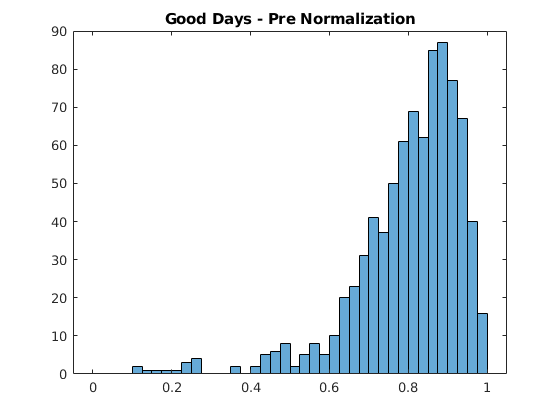


histogram(GD, edges)
title('Good Days - Pre Normalization')

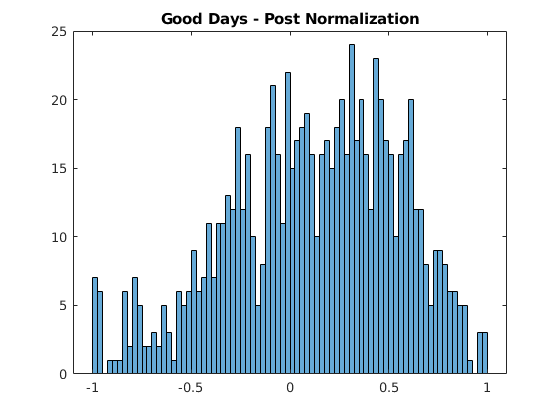


GDN = 2.*(GD).^3-1;
histogram(GDN, edgesN)
title('Good Days - Post Normalization')

%MD 
minMD = min(MD)

minMD = 0.0014

maxMD = max(MD)

maxMD = 0.7120

nnzMD = nnz(MD) 

nnzMD = 832

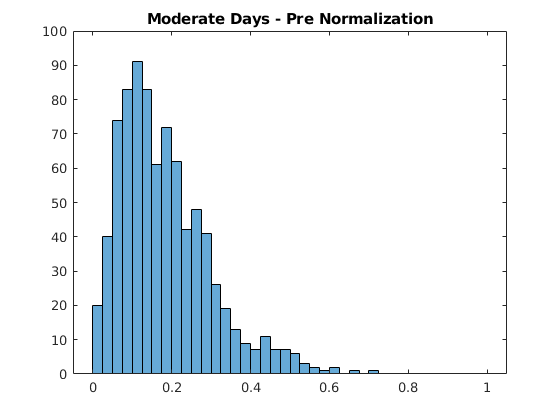


histogram(MD, edges)
title('Moderate Days - Pre Normalization')


nnzMD_V = MD(MD~=0);
medMD_V = median(nnzMD_V);

MDN = tanh(7*(MD-0.2));

minMDN = min(MDN)

minMDN = -0.8832

maxMDN = max(MDN)

maxMDN = 0.9985

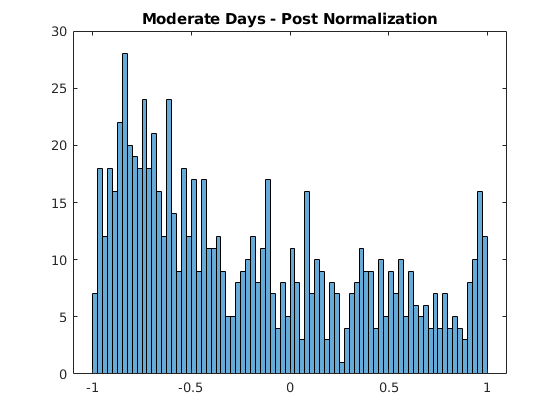

MDN = 2*((MDN-minMDN)/(maxMDN-minMDN))-1;
histogram(MDN, edgesN)
title('Moderate Days - Post Normalization')

%UFSGD
minUFSGD = min(UFSGD)

minUFSGD = 0

maxUFSGD = max(UFSGD)

maxUFSGD = 0.2822

nnzUFSGD = nnz(UFSGD)

nnzUFSGD = 756

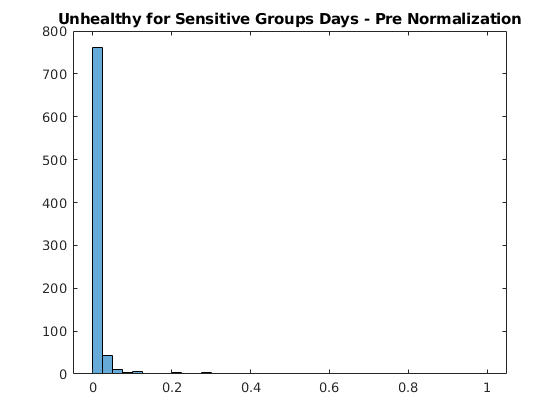


histogram(UFSGD, edges)
title('Unhealthy for Sensitive Groups Days - Pre Normalization')

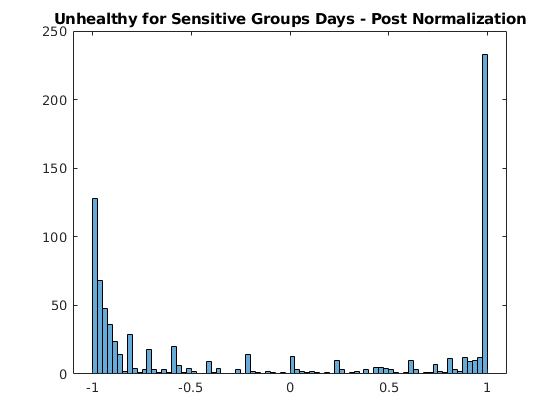


nnzUFSGD_V = UFSGD(UFSGD~=0);
medUFSGD_V = median(nnzUFSGD_V);

UFSGDN = tanh(500*(UFSGD-0.005));
%minUFSGDN = min(UFSGDN)
%maxUFSGDN = max(UFSGDN)

%UFSGDN = 2*((UFSGDN-minUFSGDN)/(maxUFSGDN-minUFSGDN))-1;
histogram(UFSGDN, edgesN)
title('Unhealthy for Sensitive Groups Days - Post Normalization')

%UD
minUD = min(UD)

minUD = 0

maxUD = max(UD)

maxUD = 0.3305

nnzUD = nnz(UD)

nnzUD = 351

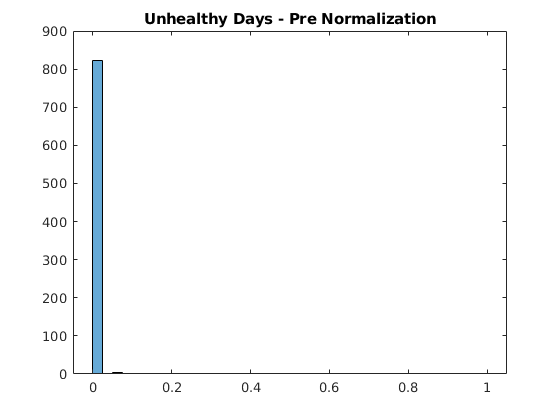


histogram(UD, edges)
title('Unhealthy Days - Pre Normalization')

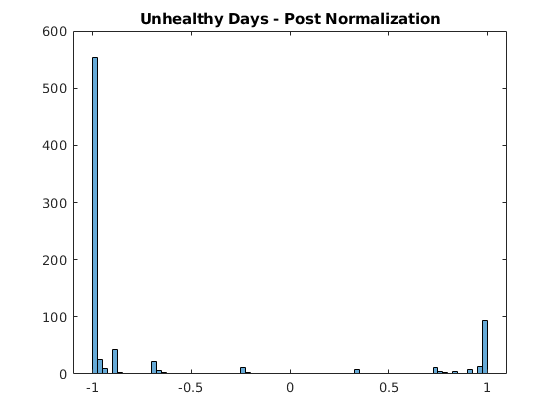


nnzUD_V = UD(UD~=0);
medUD_V = median(nnzUD_V);

UDN = tanh(1300*(UD-0.002));
minUDN = min(UDN);
maxUDN = max(UDN);

UDN = 2*((UDN-minUDN)/(maxUDN-minUDN))-1;
histogram(UDN,edgesN)
title('Unhealthy Days - Post Normalization')

%VUD
minVUD = min(VUD)

minVUD = 0

maxVUD = max(VUD)

maxVUD = 0.0256

nnzVUD = nnz(VUD)

nnzVUD = 79

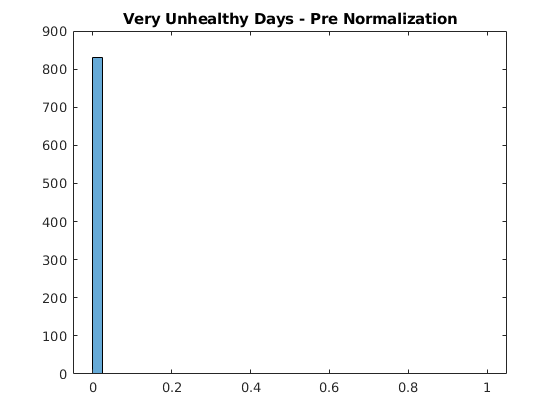


histogram(VUD, edges)
title('Very Unhealthy Days - Pre Normalization')

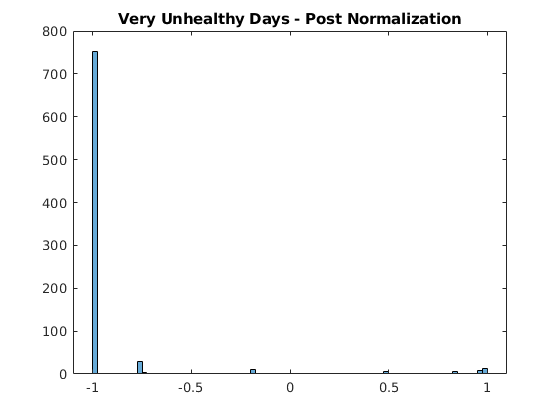


nnzVUD_V = VUD(VUD~=0);
medVUD_V = median(nnzVUD_V);

% t = 100*VUD
% tt = t(t~=0)
% sort(t, 'descend')
% ttt = tanh(5*(tt-0.35)); 
% histogram(ttt, edgesN)

VUDN = tanh(1500*(VUD-0.001));
minVUDN = min(VUDN);
maxVUDN = max(VUDN);

VUDN = 2*((VUDN-minVUDN)/(maxVUDN-minVUDN))-1;

histogram(VUDN,edgesN)
title('Very Unhealthy Days - Post Normalization')

%HD
minHD = min(HD)

minHD = 0

maxHD = max(HD)

maxHD = 0.0310

nnzHD = nnz(HD)

nnzHD = 34

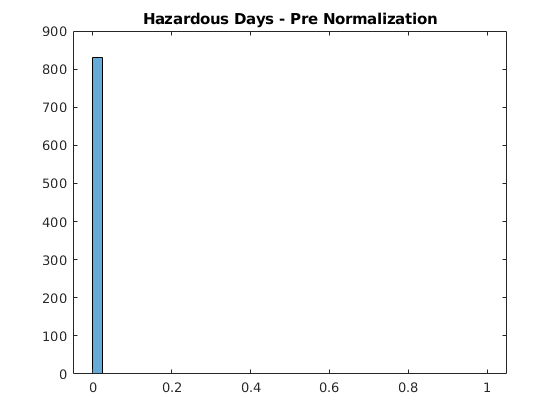


histogram(HD, edges)
title('Hazardous Days - Pre Normalization')

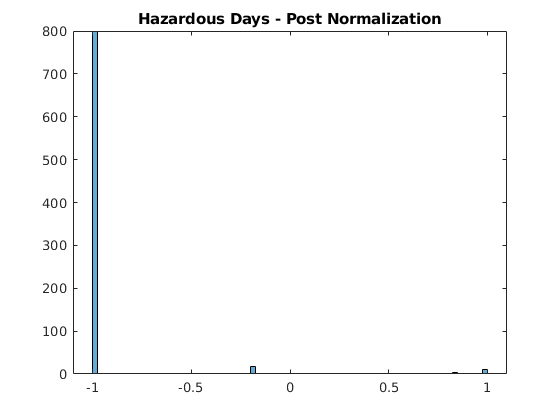


nnzHD_V = HD(HD~=0);
medHD_V = median(nnzHD_V);

HDN = tanh(3000*(HD-0.0005));
minHDN = min(HDN);
maxHDN = max(HDN);

HDN = 2*((HDN-minHDN)/(maxHDN-minHDN))-1;
histogram(HDN, edgesN)
title('Hazardous Days - Post Normalization')

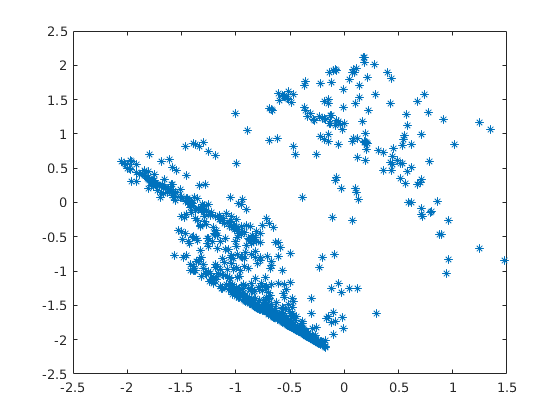

NormMat = [GDN MDN UFSGDN UDN VUDN HDN];

%PCA Test
pca_red2 = PCA(NormMat, 2);
plot(pca_red2(:,1), pca_red2(:,2), '*')

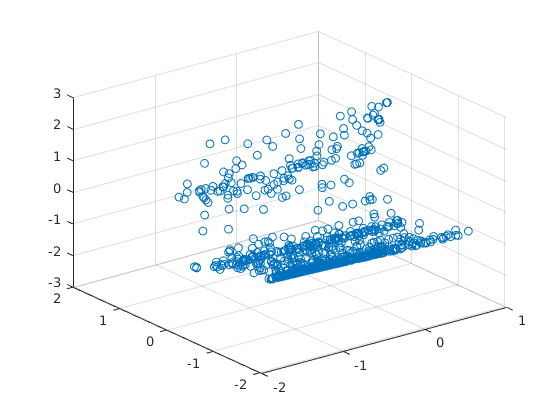


pca_red3 = PCA(NormMat, 3);
scatter3(pca_red3(:,1), pca_red3(:,2), pca_red3(:,3))

[t_RND, C_RND] = kmeans(NormMat, 3)

t_RND =      1
     1
     1
     3
     1
     2
     1
     2
     1
     1


C_RND =     0.3298   -0.4685   -0.8419   -0.9578   -0.9929   -0.9945
   -0.0603    0.0468    0.7883   -0.9238   -0.9959   -0.9883
   -0.2400    0.1895    0.8505    0.9126   -0.4707   -0.7272


RND_kC1 = RD(t_RND ==1,:)

RND_kC1 =     0.8766    0.1210    0.0024         0         0         0
    0.9160    0.0834    0.0006         0         0         0
    0.8898    0.1093    0.0009         0         0         0
    0.9106    0.0888    0.0006         0         0         0
    0.8159    0.1831    0.0010         0         0         0
    0.6320    0.3648    0.0023    0.0005    0.0005         0
    0.8409    0.1581    0.0009         0         0         0
    0.7214    0.2770    0.0016         0         0         0
    0.9092    0.0902    0.0005         0         0         0
    0.7099    0.2891    0.0010         0         0         0


RND_kC2 = RD(t_RND ==2,:)

RND_kC2 =     0.4692    0.5089    0.0210    0.0009         0         0
    0.7708    0.2216    0.0076         0         0         0
    0.8691    0.1207    0.0102         0         0         0
    0.7341    0.2599    0.0060         0         0         0
    0.7716    0.2223    0.0060         0         0         0
    0.5628    0.4245    0.0128         0         0         0
    0.7700    0.2235    0.0065         0         0         0
    0.8006    0.1833    0.0161         0         0         0
    0.8375    0.1524    0.0100         0         0         0
    0.4806    0.4975    0.0215    0.0005         0         0


RND_kC3 = RD(t_RND ==3,:)

RND_kC3 =     0.6876    0.3049    0.0037    0.0038         0         0
    0.2670    0.4149    0.2665    0.0516         0         0
    0.1625    0.7120    0.1182    0.0050    0.0023         0
    0.2342    0.6116    0.1132    0.0183    0.0050    0.0178
    0.7647    0.2280    0.0046    0.0027         0         0
    0.6636    0.3008    0.0306    0.0027    0.0018    0.0005
    0.6038    0.3615    0.0260    0.0073    0.0014         0
    0.4747    0.4742    0.0402    0.0078    0.0014    0.0018
    0.6252    0.3367    0.0326    0.0046    0.0005    0.0005
    0.7106    0.2702    0.0096    0.0091    0.0005         0


SC_idx = spectralcluster(NormMat, 3);
RND_sC1 = RD(SC_idx ==1,:)

RND_sC1 =     0.8766    0.1210    0.0024         0         0         0
    0.9160    0.0834    0.0006         0         0         0
    0.8898    0.1093    0.0009         0         0         0
    0.9106    0.0888    0.0006         0         0         0
    0.8409    0.1581    0.0009         0         0         0
    0.9092    0.0902    0.0005         0         0         0
    0.9954    0.0046         0         0         0         0
    0.9695    0.0300    0.0005         0         0         0
    0.9670    0.0330         0         0         0         0
    0.9397    0.0603         0         0         0         0


RND_sC2 = RD(SC_idx ==2,:)

RND_sC2 =     0.4692    0.5089    0.0210    0.0009         0         0
    0.8159    0.1831    0.0010         0         0         0
    0.7708    0.2216    0.0076         0         0         0
    0.6320    0.3648    0.0023    0.0005    0.0005         0
    0.7214    0.2770    0.0016         0         0         0
    0.8691    0.1207    0.0102         0         0         0
    0.7099    0.2891    0.0010         0         0         0
    0.7234    0.2725    0.0041         0         0         0
    0.7341    0.2599    0.0060         0         0         0
    0.7716    0.2223    0.0060         0         0         0


RND_sC3 = RD(SC_idx ==3,:)

RND_sC3 =     0.6876    0.3049    0.0037    0.0038         0         0
    0.2670    0.4149    0.2665    0.0516         0         0
    0.1625    0.7120    0.1182    0.0050    0.0023         0
    0.2342    0.6116    0.1132    0.0183    0.0050    0.0178
    0.7647    0.2280    0.0046    0.0027         0         0
    0.6636    0.3008    0.0306    0.0027    0.0018    0.0005
    0.6038    0.3615    0.0260    0.0073    0.0014         0
    0.4747    0.4742    0.0402    0.0078    0.0014    0.0018
    0.6252    0.3367    0.0326    0.0046    0.0005    0.0005
    0.7106    0.2702    0.0096    0.0091    0.0005         0


compclass = data(:,[1:9]);
compclass.AQI_Class_KM = t_RND;
compclass.AQI_Class_SC = SC_idx;

writetable(compclass, 'Datasets/AQI_Class_Comparison.csv')

ndata = data(:,[1,2,3,10,11,12]);
ndata.AQI_Class_KM = t_RND;
ndata.AQI_Class_SC = SC_idx;
ndata

ndata = 832×8 table
       State           County                 CS              MaxAQI    x90thPercentileAQI    MedianAQI    AQI_Class_KM    AQI_Class_SC
    ___________    ______________    _____________________    ______    __________________    _________    ____________    ____________

    {'Alabama'}    {'Baldwin'   }    {'BaldwinAlabama'   }     129            52.667           36.833           2               3      
    {'Alabama'}    {'Colbert'   }    {'ColbertAlabama'   }     115            49.667           36.667           2               3      
    {'Alabama'}    {'DeKalb'    }    {'DeKalbAlabama'    }     119            51.833               38           2               3      
    {'Alabama'}    {'Etowah

%writetable(ndata, 'Datasets/AQI_Features.csv')
%writetable(ndata, '/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/AQI_Features.csv')

function Reduced_Data = PCA(data, dim)
    d_mean = mean(data);
    data_zmean = data-d_mean; 
    
    C = cov(data_zmean); 
    [e,v] = eig(C);
    
    v = diag(v);
    
    W = e(:,end-(dim-1):end);
    Reduced_Data = data*W;
end 
